Xc = -20; 
Yc = 180; 
alpha = deg2rad(30);

r = 130;
Sa = 170; 
L = 130; 

% Base Joint Positions
PB = [(-145*sqrt(3)), 0; (145*sqrt(3)), 0; 0, 435];

[theta, PP] = inverse_kinematics(Xc, Yc, r, alpha, Sa, L, PB);

disp(theta);

    1.1464   -0.3755
    2.8327    1.6389
   -1.3143   -2.9034



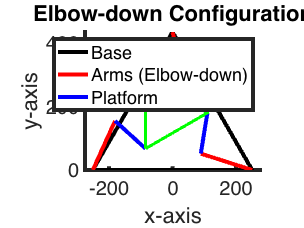

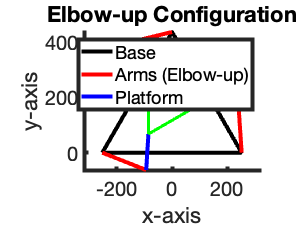

% Check if inverse kinematics solution is valid
% Check if inverse kinematics solution is valid
if isempty(theta)
    disp('Unreachable configuration. Skipping plot.');
else
    % Plot Elbow-down Configuration (c(i) - d(i))
    figure;
    hold on;
    axis equal;
    xlabel('x-axis', 'FontSize', 20);
    ylabel('y-axis', 'FontSize', 20);
    set(gca, 'LineWidth', 4, 'FontSize', 20);
    title('Elbow-down Configuration');
    
    % Plot Base
    plot([PB(1,1), PB(2,1), PB(3,1), PB(1,1)], ...
         [PB(1,2), PB(2,2), PB(3,2), PB(1,2)], 'k-', 'LineWidth', 4);

    for i = 1:3
        % Joint angles for elbow-down
        theta_config = theta(i, 1);  % Elbow-down configuration
        
        % Calculate M (intermediate joint)
        vector_M = [cos(theta_config), sin(theta_config)];
        M = PB(i, :) + Sa * vector_M;
        
        % Calculate vector from M to PP
        vector_PP = PP(i, :) - M;
        vector_PP_normalized = L * (vector_PP / norm(vector_PP));
        PP_actual = M + vector_PP_normalized;
        
        % Plot arm from PB to M
        plot([PB(i, 1), M(1)], [PB(i, 2), M(2)], 'r-', 'LineWidth', 4);  % Red line
        % Plot arm from M to PP_actual
        plot([M(1), PP_actual(1)], [M(2), PP_actual(2)], 'b-', 'LineWidth', 4);  % Blue line
    end

    % Plot Platform
    plot([PP(:,1); PP(1,1)], [PP(:,2); PP(1,2)], 'g-', 'LineWidth', 3);
    legend('Base', 'Arms (Elbow-down)', 'Platform');

    % Plot Elbow-up Configuration (c(i) + d(i))
    figure;
    hold on;
    axis equal;
    xlabel('x-axis', 'FontSize', 20);
    ylabel('y-axis', 'FontSize', 20);
    set(gca, 'LineWidth', 4, 'FontSize', 20);
    title('Elbow-up Configuration');
    
    % Plot Base
    plot([PB(1,1), PB(2,1), PB(3,1), PB(1,1)], ...
         [PB(1,2), PB(2,2), PB(3,2), PB(1,2)], 'k-', 'LineWidth', 4);

    for i = 1:3
        % Joint angles for elbow-up
        theta_config = theta(i, 2);  % Elbow-up configuration
        
        % Calculate M (intermediate joint)
        vector_M = [cos(theta_config), sin(theta_config)];
        M = PB(i, :) + Sa * vector_M;
        
        % Calculate vector from M to PP
        vector_PP = PP(i, :) - M;
        vector_PP_normalized = L * (vector_PP / norm(vector_PP));
        PP_actual = M + vector_PP_normalized;
        
        % Plot arm from PB to M
        plot([PB(i, 1), M(1)], [PB(i, 2), M(2)], 'r-', 'LineWidth', 4);  % Red line
        % Plot arm from M to PP_actual
        plot([M(1), PP_actual(1)], [M(2), PP_actual(2)], 'b-', 'LineWidth', 4);  % Blue line
    end

    % Plot Platform
    plot([PP(:,1); PP(1,1)], [PP(:,2); PP(1,2)], 'g-', 'LineWidth', 3);
    legend('Base', 'Arms (Elbow-up)', 'Platform');
end